# WAYPOINTS

Seguimiento de una trayectoria mediante un robot móvil diferencial utilizando el **algoritmo Pure Pursuit**, haciendo uso del toolbox de **Robotics System Toolbox**.

Se define el modelo cinemático del robot diferencial mediante el objeto `DifferentialDrive`.

%% Define Vehicle
R = 0.5;                % Wheel radius [m]
L = 0.18;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

Se configura el tiempo de muestreo, duración de la simulación y posición inicial del robot.

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:77;         % Time array

initPose = [0;3;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

En esta sección calcula las velocidades necesarias para seguir la trayectoria, porque se configura la Distancia de anticpación "LookaheadDistance, en cuanto más grade se puede presentar mejor curvas, también encontrmaos la velocidad lineal deseada y velocidad angular máxima, para mejor las curvas en movimiento pronunciados

% Define waypoints
waypoints =[0,3; 2,1 ; 4,1 ; 6,1 ; 8,3 ;6,3 ; 4,1 ; 4,5; 6,3; 6,5; 8,5;...
    6,7; 8,9 ; 6,9; 6,11; 4,9; 4,8; 5,8; 5,6; 3,6; 3,8; 4,8; 4,9; 2,11;...
    2,9; 0,9; 2,7; 0,5; 2,5; 2,3; 4,5; 4,1; 2,3; 0,3]

waypoints =      0     3
     2     1
     4     1
     6     1
     8     3
     6     3
     4     1
     4     5
     6     3
     6     5



% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

- El controlador Pure Pursuit calcula las velocidades necesarias para que el robot siga la trayectoria.

- Se ajusta la distancia de anticipación (LookaheadDistance), velocidad deseada y máxima velocidad angular.

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 1.5;
controller.MaxAngularVelocity = 5.5;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 


Se obtienen las velocidades lineal y angular deseadas, y se transforman a velocidades de rueda.

    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    

Se calcula el desplazamiento del robot usando integración discreta (posición y orientación).

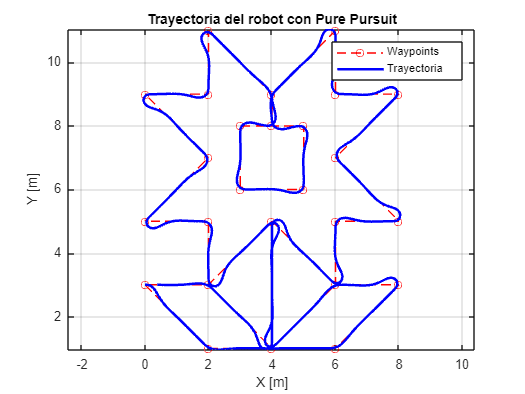

    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    %viz(pose(:,idx),waypoints); %Lo estavblecemos para no imprimir todo de golpe
    waitfor(r);
    
end

figure;
plot(waypoints(:,1), waypoints(:,2), 'ro--', 'DisplayName', 'Waypoints'); hold on;
plot(pose(1,:), pose(2,:), 'b-', 'LineWidth', 2, 'DisplayName', 'Trayectoria');
legend;
title('Trayectoria del robot con Pure Pursuit');
xlabel('X [m]');
ylabel('Y [m]');
axis equal;

grid on;
